# How to Connect the PEMFC system to ThingSpeak

[⇦ Return to the main menu](matlab:open('..\MainMenu.m'))

In this script, you will communicate to the PEMFC system to collect data via cloud platform. The system performance is based on measuring voltage and current variables. The MATLAB logger acts as the central communication hub between the laboratory instruments and the cloud platform.

Complete Data Flow:

Sensors

   ↓

MATLAB Logger

   ↓

CSV File (Local Storage)

   ↓

ThingSpeak Cloud

   ↓

Online Dashboard

## **Before you get started**

Consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## 1. Introduction

The Internet of Things (IoT) refers to the network of interconnected devices, objects, and systems that can communicate and exchange data over the Internet. It enables everyday objects like appliances, vehicles, and wearable devices to connect and interact, creating a seamless and intelligent network of physical objects. IoT has revolutionized various industries by enabling data-driven decision-making, automation, and enhanced connectivity, ultimately leading to increased efficiency, convenience, and innovation in our daily lives.

**ThingSpeak**

ThingSpeak is an IoT platform developed by MathWorks. It provides a convenient and easy-to-use interface for collecting, analyzing, and visualizing data from your IoT devices. With ThingSpeak, users can create IoT applications and projects by integrating sensors, actuators, and other devices and monitor and control them remotely. It also offers features like data logging, real-time data visualization, and the ability to trigger actions based on specific conditions, making it a versatile platform for building IoT solutions.

We will leverage ThingSpeak with our Arduino board to send an alert when the fuel cell temperature, current or voltage exceeds a certain value.

Before starting the fuel cell, we should explore some of ThingSpeak's functionalities. Here's tutorial on how to use ThingSpeak: [https://www.mathworks.com/help/thingspeak/getting-started-with-thingspeak.html](https://www.mathworks.com/help/thingspeak/getting-started-with-thingspeak.html) 

## **2. Collect data from a public channel**

In ThingSpeak, all of the data are stored on a **channel.** In general, each connected device will use its own channel. Larger projects might require multiple channels. Like social media profiles or video content shared online, your channel can be public or private. Public channels allow you to share the data with anyone, while private channels require you to share access with another user if you want to share.

The fuel cell system data is available on a ThingSpeak public channel.

  **Try.** Visit the channel page to familiarize yourself with the user interface.

web("https://thingspeak.com/channels/3405879")
 

  **Exercise.** What kind of data is stored on this channel?

DataOnChannel( ...
   false,  false,  false,  false ); % PEMFC Voltage, PEMFC Current, PEMFC Temperature, Hydrogen Pressure
 

## **3. Create your private channel**

Now that you understand the data that can be stored on a ThingSpeak channel, you should try creating your own. Before getting started, return to the ThingSpeak [website](https://thingspeak.com/) and connect to your account.

- In the top menu, click **Channels > My Channels**

- Click **New Channel**

- Name your channel:** PEMFC_Testing**

- Name the fields: 

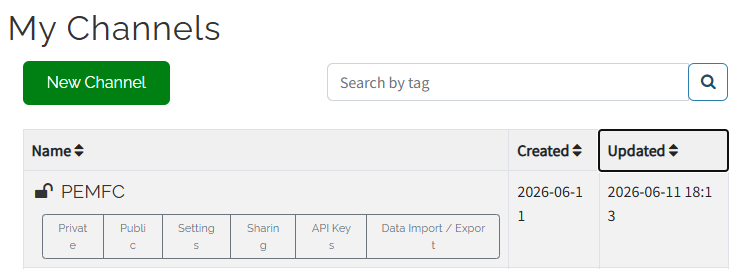

Screenshot on creating and naming channel

Table that shows the names and description of the fields

** Notes:**

- For better visuals make sure to include the units in the field name.

- Pay attention to the order of the Fields as it will be used later in the code script.

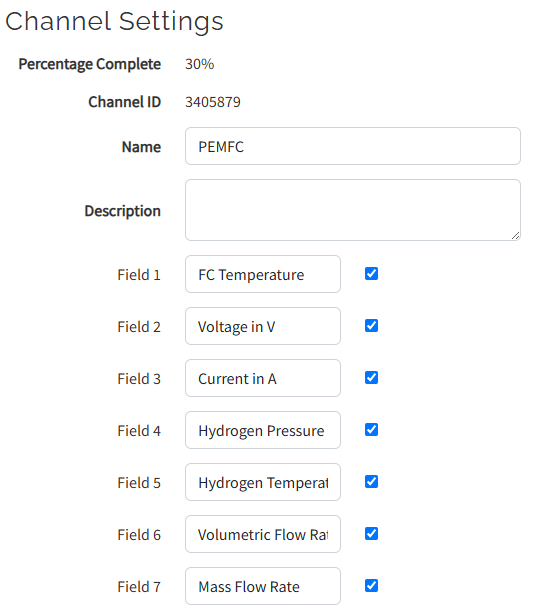

Finally, scroll down in the same page and press "Save Channel" green button.

 **Exercise.** After saving the channel, switch the view to the **API Keys **tab and paste your channel-specific information in the fields below.

clear
% Initialize the ThingSpeak channel
ChannelID = NaN;
WriteAPIKey = "";
ReadAPIKey = ""; 
% CheckChannelCreated(ChannelID,WriteAPIKey,ReadAPIKey)
 

### 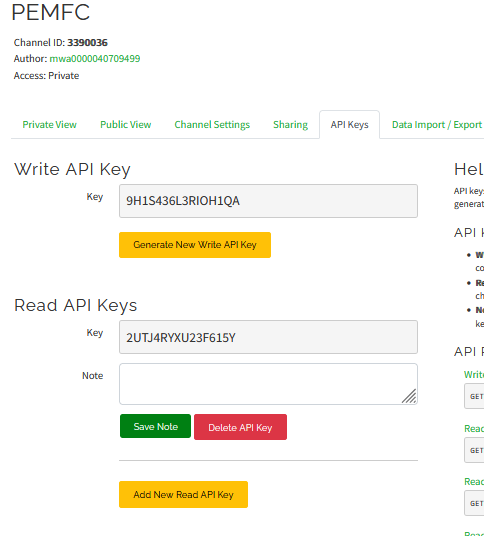

Screenshot of obtaining API Key and channel info to input

## **4. Send data to a channel**

After successfully creating your first ThingSpeak channel, the next step is to generate or obtain offline example data to be transmitted to the channel. This signal can be simulated or generated using various methods, such as mathematical functions or predefined data. By sending this signal to the channel, you can test and analyze the functionality of the IoT devices and applications to ensure they are properly integrated and capable of transmitting and receiving data.

### **Read the data from example file**

The example file (such as Excel and CSV) represents offline PEMFC measurements collected from an earlier run. Each row is one time sample from the experiment or model.

excelFile = "Data\Example_PEMFC_data_2026.xlsx";

Tdata = readtable(excelFile, ...
    "FileType", "spreadsheet", ...
    "VariableNamingRule", "preserve");

Tdata.Properties.VariableNames = ...
    cellstr(strtrim(string(Tdata.Properties.VariableNames)));

disp("Detected Excel columns:");
disp(Tdata.Properties.VariableNames');
 

### **Map CSV columns to variables**

The raw CSV columns are renamed into clear PEMFC engineering variables. This improves readability and reduces mistakes during upload.

realTemperature   = Tdata.("Temperature Tfc (°C)");
realVoltage       = Tdata.("Voltage (V)");
realCurrent       = Tdata.("Current (A)");
realH2Pressure    = Tdata.("H2 Pressure (bar)");
realH2Temperature = Tdata.("H2 Temperature (°C)");
realH2VFlow       = Tdata.("H2 Flow_vol (L/s)");
realH2MFlow       = Tdata.("H2 Flow_mass (g/s)");
realTime          = (0:height(Tdata)-1)' * 20;   
 

Locate the variables already generated by the PEMFC MATLAB model.

Extract the following measurements:

 Ask Copilot: “Why is correct field mapping important when uploading PEMFC data to ThingSpeak?”

### **Data Acquisition and Upload Timing**

MATLAB collects data at given rate while ThingSpeak uploads at a fixed rate.

Ts = 0.2;                    % Local data sampling time [s]
Sampling_Frequency = 1 / Ts; % Local sampling frequency [Hz]
sendInterval_s = 20; % ThingSpeak upload interval [s]
sampleTime = 20;
numSamples = height(Tdata)/10
 

This separation allows high-speed local logging while respecting ThingSpeak upload limits.

### **Prepare Fields and Upload the Data to ThingSpeak**

The fields are prepared based on the variables from the data collected. The information is entered in MATLAB before sending to Thingspeak to be recorded. The channel ID and Write API key in the MATLAB code are used and then the `thingSpeakWrite` command is kept. Finally, the command is updated so that it uploads the **PEMFC values.**

 Exercise : Upload One PEMFC Sample

Complete the ThingSpeak command below.

Required inputs:

- Channel ID

- Field numbers

- PEMFC values

- Write API Key

%% Prepare ThingSpeak Fields
fprintf('Data upload running. This may take a few minutes');
fieldsToUpload = [1 2 3 4 5 6 7]; % field number to assign to labeled variables
for k = 1:numSamples % number of data samples in a for loop

    t = realTime(k); % represent discretized time based on sample number

    Tfc_C   = realTemperature(k); % FC Temperature [C]
    V_V     = realVoltage(k); % FC Voltage [V]
    I_A     = realCurrent(k); % FC current [A]
    P_omega = realH2Pressure(k); % Hydrogen pressure [bar]
    T_omega = realH2Temperature(k); % Hydrogen temperature [C]
    Q_vol   = realH2VFlow(k);    % Volumetric flow rate [L/s]
    Q_mass  = realH2MFlow(k);    % Mass flow rate [g/s]

    valuesToUpload = [ ...
        Tfc_C, ...
        V_V, ...
        I_A, ...
        P_omega, ...
        T_omega, ...
        Q_vol, ...
        Q_mass];
    try
        thingSpeakWrite(ChannelID, ...
            "Fields", fieldsToUpload, ...
            "Values", valuesToUpload, ...
            "WriteKey", WriteAPIKey);
        fprintf("%02d | Uploaded | t = %.2f s | Tfc = %.2f C | V = %.3f V | I = %.3f A | H2 P = %.3f bar | H2 T = %.2f C | Qvol = %.4f L/s | Qmass = %.4f g/s\n", ...
            k, t, Tfc_C, V_V, I_A, P_omega, T_omega, Q_vol, Q_mass);

    catch ME
        fprintf("Upload failed at sample %d: %s\n", k, ME.message);
    end

    pause(sampleTime);

end
 

## **5. Run the data file and Verify the Channel**

**⚠️ Common Troubleshooting**

If no data appears:

- Verify Channel ID

- Verify Write API Key

- Verify internet connection

- Verify ThingSpeak field mapping

- Verify upload interval

Check the channel if the data was uploaded properly.

url = ['https://thingspeak.com/channels/' num2str(ChannelID) '/private_show'];
web(url)
 

Ask Copilot: “If the ThingSpeak dashboard shows unrealistic PEMFC values, what should be checked first?”

**🎯  Checkpoint**

Before proceeding, answer the following:

- Does each field represent a real physical variable?

- Are the displayed units correct?

- Can another engineer understand the dashboard without additional explanation?

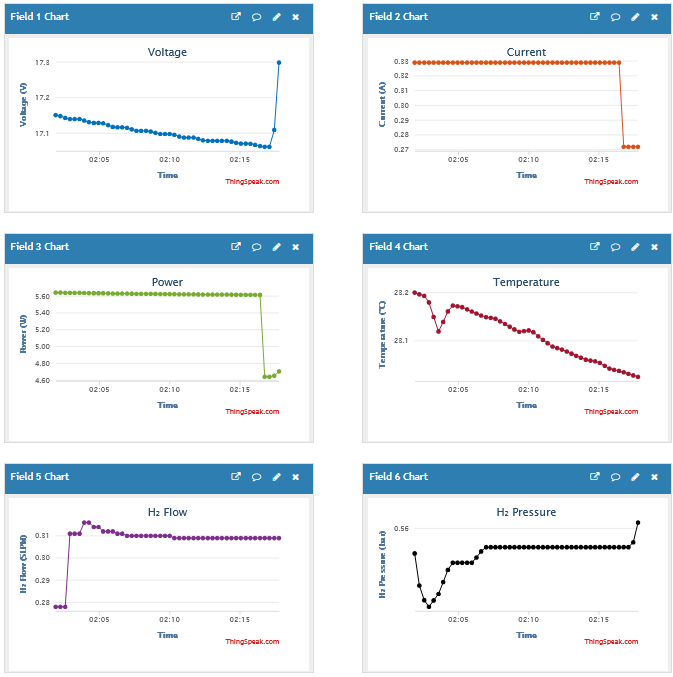

Screenshot of the expected data collected on Thingspeak

## **6. Use the Same Structure for Future Expansion**

- Once the real PEMFC outputs are successfully uploaded, the same connection can be extended to additional parameters such as flow rate or fan data. 

- The artificial-data script is only used as an initial communication test and should not remain in the final version.

📖 Code Example: Uploading PEMFC Data to ThingSpeak

The following code demonstrates how MATLAB uploads PEMFC measurements to a ThingSpeak channel. This example is provided for reference and is intentionally commented out to prevent accidental data uploads. To execute the code, Ensure that `channelID`, `writeAPIKey`, `fieldsToUpload`, and `valuesToUpload` have already been defined.

**Important note: **ThingSpeak free channels should not be updated faster than every 15 seconds. If data is sent too quickly, uploads may fail or be rejected. In this script, sampleTime = 20 seconds is safe for a free ThingSpeak channel.

 Ask Copilot: “Explain how PEMFC voltage, current, temperature, hydrogen pressure, and hydrogen flow together describe the fuel-cell operating condition.”

## 7. Read PEMFC Data from ThingSpeak and Save as CSV

In this section, MATLAB reads PEMFC measurements from the ThingSpeak channel and saves them as a CSV file.

This step represents the second direction of the digital-twin workflow:

ThingSpeak cloud data → MATLAB table → local CSV file

### **Confirm the ThingSpeak Reading Information **

The Channel ID tells MATLAB which ThingSpeak channel to read from.

The Read API Key gives MATLAB permission to access the data stored in that channel.

The variable numPoints controls how many recent data points MATLAB will download.

%% % Step 1: Configure ThingSpeak Read Settings
ChannelID  = NaN;
ReadAPIKey = "";
numPoints = 100;

### **Read Data from ThingSpeak**

MATLAB now requests the latest PEMFC measurements from Fields 1–7 of the ThingSpeak channel.

Field mapping:

Field 1 → Fuel Cell Temperature (°C)

Field 2 → Voltage (V)

Field 3 → Current (A)

Field 4 → Hydrogen Pressure (bar)

Field 5 → Hydrogen Temperature (°C)

Field 6 → Hydrogen Volumetric Flow Rate (L/s)

Field 7 → Hydrogen Mass Flow Rate (g/s)

📖 Code Example. Reading data from your private channel.

T = thingSpeakRead(ChannelID, ...
    "Fields", [1 2 3 4 5 6 7], ...
    "NumPoints", numPoints, ...
    "ReadKey", ReadAPIKey, ...
    "OutputFormat", "table");
 

### ️Preview the Downloaded Data

Before saving the data, display the table in MATLAB to confirm that values were successfully downloaded.

disp("Data read from ThingSpeak:");
disp(T);
 

### Rename columns

ThingSpeak returns default field names (Field1–Field7). To make the table easier to understand, rename the columns using the same MATLAB labels adopted throughout this laboratory exercise.

T.Properties.VariableNames = { ...
    'Time', ...
    'Tfc_C', ...
    'V_V', ...
    'I_A', ...
    'P_omega', ...
    'T_omega', ...
    'Q_vol', ...
    'Q_mass'};
 

### Choose save location

The file will be saved in the current MATLAB working folder.

outputFile = fullfile(pwd, "thingspeak_pemfc_data.csv")

fprintf("Saving CSV to:\n%s\n", outputFile)
 

### Save the Table as a CSV File and Confirm the CSV File Was Created

The writetable function exports the downloaded ThingSpeak data into a CSV file. This checkpoint verifies that MATLAB successfully created the CSV file.

writetable(T, outputFile);

if isfile(outputFile)
    disp("DONE: CSV file created successfully.")
else
    disp("ERROR: CSV file was not created.")
end
 

**📖 Code Example**

The following code is provided as a reference and is intentionally commented out.

To execute the example:

• Leave the `%%` section header unchanged.

• Ensure that all required variables have already been defined.

⚠️ Important

The `%%` symbol creates a MATLAB Live Script section and should not be removed.

Only remove the single `%` symbols that comment out the executable code.

**Charts of the measured variables after reading the data:**

## Helper Functions

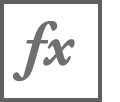`DataOnChannel`

function DataOnChannel(a1,a2,a3,a4)
answer = [a1,a2,a3,a4];
if all(answer)
    disp("Good job! You found all the data registered on this channel.")
else
    warning("You are missing some of the data registered on the channel")
end
end

[⇦ Return to the main menu](matlab:open('..\MainMenu.m'))

Copyright